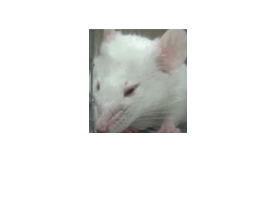

clc; clear; close all

img=imread('Test_rat_image3.png'); % Insert image of here
imshow(img)

I=rgb2gray(img);


[I_test, threshold]=edge(I,'Canny');

Threshold (adjust slider that isolates the eyes the most)

threshold;
% adjust threshold till there is no error or eye is isolated
I_edge=edge(I,'Canny',4.2* threshold); 

Eye isolation

se90=strel('line',3,90);
se0=strel('line',3,0);
I_dilate=imdilate(I_edge,[se90 se0]);

I_fill=imfill(I_dilate,'holes');

I_erode=imerode(I_fill,[se90 se0]);
I_erode=imerode(I_erode,[se90 se0]);
I_clear=imclearborder(I_erode);

I_final=labeloverlay(img,I_clear);

Final images

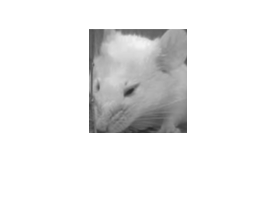

imshow(I)

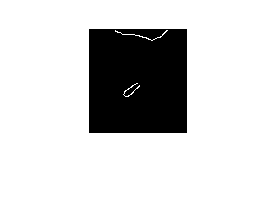

imshow(I_edge)

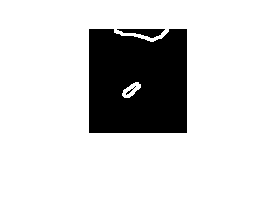

imshow(I_dilate)

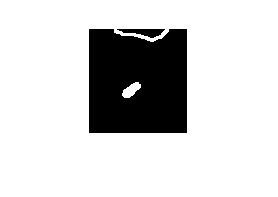

imshow(I_fill)

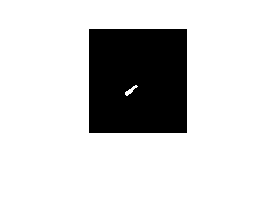

imshow(I_erode)

imshow(I_clear)

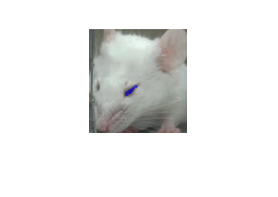

imshow(I_final)

Calculation of eye's area (biggest on image) 


region=regionprops(I_clear,'Area','Centroid','orientation','MajoraxisLength','MinoraxisLength','BoundingBox')

region = struct with fields:
               Area: 52
           Centroid: [42.2692 62.1346]
        BoundingBox: [36.5000 56.5000 13 11]
    MajorAxisLength: 16.6913
    MinorAxisLength: 4.4207
        Orientation: 39.3778


Area=[region.Area]

Area = 52

eye_target=find(Area==max(Area))

eye_target = 1


% field that contains biggest area
eye_data=region(eye_target)

eye_data = struct with fields:
               Area: 52
           Centroid: [42.2692 62.1346]
        BoundingBox: [36.5000 56.5000 13 11]
    MajorAxisLength: 16.6913
    MinorAxisLength: 4.4207
        Orientation: 39.3778



% we want to evaluate the image of the best/biggest eye
bigeye_Area=Area(eye_target) 

bigeye_Area = 52


BoundingBox=eye_data.BoundingBox

BoundingBox =    36.5000   56.5000   13.0000   11.0000



X_dimension=BoundingBox(3);

X_dimension = 13

Y_dimension=BoundingBox(4);

Y_dimension = 11


XY_ratio= Y_dimension/X_dimension

XY_ratio = 0.8462


MajorAxis=eye_data.MajorAxisLength

MajorAxis = 16.6913

MinorAxis=eye_data.MinorAxisLength

MinorAxis = 4.4207


Major_Minor_Ratio=MajorAxis/MinorAxis

Major_Minor_Ratio = 3.7757




% !!!!!!!Major_Minor_Ratio: The closer to 1 the ratio, the more circular it is; if
% greater or less than 1, the more squintier the eye (more pain); I think
% it should be strictly greater than 1 and not less than; but thats because
% that is assuming the majorAxis  of a rat in pain is more horizontal. 
% !!!!!!!!
